# Práctica 1 - Cortocircuitos I - Apartado A

## Sistemas Eléctricos y de Potencia

Pablo García Peris - 53310

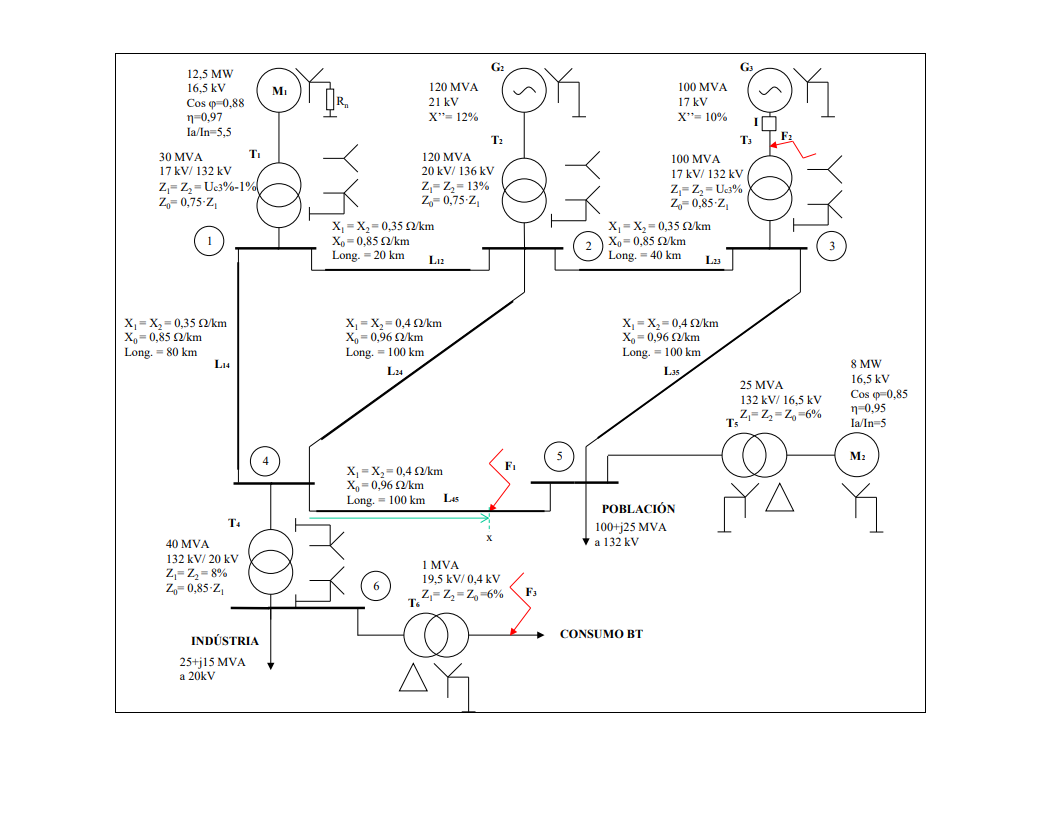

clear
clc
format shortG

imshow('Enunciado.png');

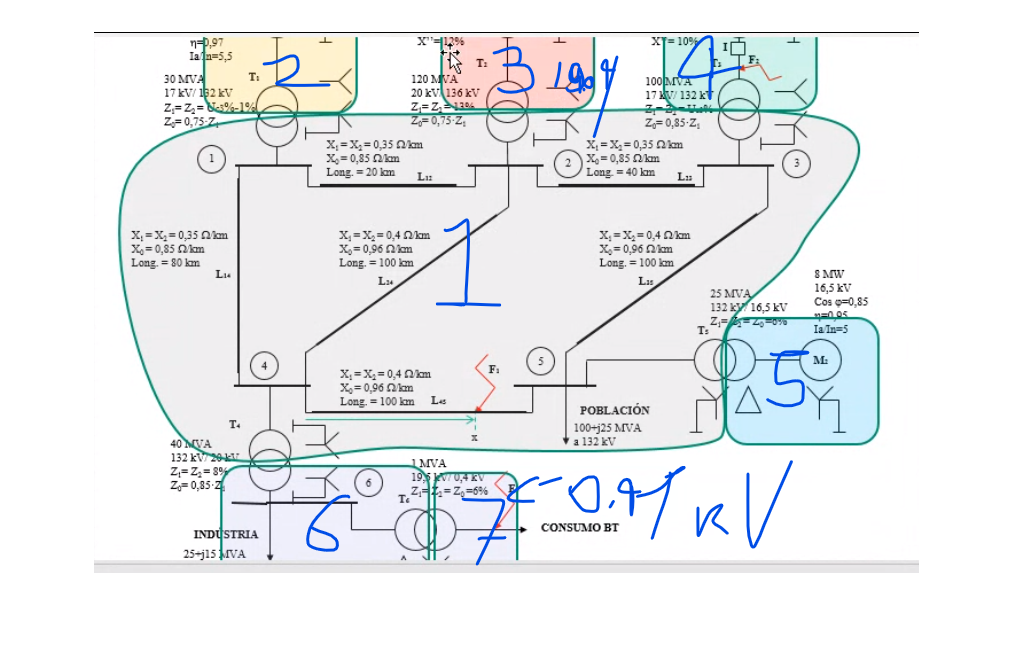

imshow('Zonas.png');

## Definición de constantes

% Unidades
k = 1e3;
M = 1e6;

Sbase = 100*M;

% Nº de matrícula
Nmatricula = 53310;
Uc3 = 2*Nmatricula*1e-4;

## Zona 1

% Valores base
Ubase1 = 132*k;
Zbase1 = Ubase1^2/Sbase

Zbase1 =        174.24



% Linea L12
LongL12 = 20;
XL12(1) = 0.35;
XL12(2) = XL12(1);
XL12(3) = 0.85;

ZL12 = XL12*LongL12*1j;
ZL12pu = ZL12/Zbase1

ZL12pu =             0 +   0.040174i            0 +   0.040174i            0 +   0.097567i



% Linea L14
LongL14 = 80;
XL14(1) = 0.35;
XL14(2) = XL14(1);
XL14(3) = 0.85;

ZL14 = XL14*LongL14*1j;
ZL14pu = ZL14/Zbase1

ZL14pu =             0 +     0.1607i            0 +     0.1607i            0 +    0.39027i



% Linea L23
LongL23 = 40;
XL23(1) = 0.35;
XL23(2) = XL23(1);
XL23(3) = 0.85;

ZL23 = XL23*LongL23*1j;
ZL23pu = ZL23/Zbase1

ZL23pu =             0 +   0.080349i            0 +   0.080349i            0 +    0.19513i



% Linea L24
LongL24 = 100;
XL24(1) = 0.4;
XL24(2) = XL24(1);
XL24(3) = 0.96;

ZL24 = XL24*LongL24*1j;
ZL24pu = ZL24/Zbase1

ZL24pu =             0 +    0.22957i            0 +    0.22957i            0 +    0.55096i



% Linea L35
LongL35 = 100;
XL35(1) = 0.4;
XL35(2) = XL35(1);
XL35(3) = 0.96;

ZL35 = XL35*LongL35*1j;
ZL35pu = ZL35/Zbase1

ZL35pu =             0 +    0.22957i            0 +    0.22957i            0 +    0.55096i



% Linea L45
LongL45 = 100;
XL45(1) = 0.4;
XL45(2) = XL45(1);
XL45(3) = 0.96;
syms x; %Entre 10% y 90% (0.1 - 0.9)

%Introducir valor de x aquí
%x = 0.5;

ZL45 = XL45*LongL45*1j;
ZL45pu = ZL45/Zbase1

ZL45pu =             0 +    0.22957i            0 +    0.22957i            0 +    0.55096i



% Linea L4x

ZL4Xpu = ZL45pu*x

$$ZL4Xpu = \left(\begin{array}{ccc} \frac{250\,x\,\mathrm{i}}{1089} & \frac{250\,x\,\mathrm{i}}{1089} & \frac{200\,x\,\mathrm{i}}{363} \end{array}\right)$$


% Linea Lx5

ZLX5pu = ZL45pu*(1-x)

$$ZLX5pu = \left(\begin{array}{ccc} -\frac{250\,x\,\mathrm{i}}{1089}+\frac{250}{1089}\,\mathrm{i} & -\frac{250\,x\,\mathrm{i}}{1089}+\frac{250}{1089}\,\mathrm{i} & -\frac{200\,x\,\mathrm{i}}{363}+\frac{200}{363}\,\mathrm{i} \end{array}\right)$$

## Zona2

% Valores base
Ubase2 = 17*k;
Zbase2 = Ubase2^2/Sbase

Zbase2 =          2.89



% Motor 1
PnM1 = 12.5*M;
UnM1 = 16.5*k;
cosphiM1 = 0.88;
rendM1 = 0.97;
IaInM1 = 5.5;

SnM1 = PnM1/(cosphiM1*rendM1);
ZM1 = 1/IaInM1*UnM1^2/SnM1;
ZM1pu(1) = ZM1/Zbase2*1j;
ZM1pu(2) = ZM1pu(1);
ZM1pu(3) = ZM1pu(1)

ZM1pu =             0 +     1.1696i            0 +     1.1696i            0 +     1.1696i



% Trafo 1
SnT1 = 30*M;
UnT1 = 17*k;
ZccT1pu = (Uc3 - 1)/100;

ZT1 = ZccT1pu*UnT1^2/SnT1;
ZT1pu(1) = ZT1/Zbase2*1j;
ZT1pu(2) = ZT1pu(1);
ZT1pu(3) = 0.75*ZT1pu(1)

ZT1pu =             0 +    0.32207i            0 +    0.32207i            0 +    0.24155i



% Puesta a tierra del motor
Rn = Nmatricula*1e-5;

Rnpu(1) = 0;
Rnpu(2) = 0;
Rnpu(3) = 3*Rn/Zbase2

Rnpu =             0            0      0.55339


## Zona 3

% Valores base
Ubase3 = 132*k*20/136;
Zbase3 = Ubase3^2/Sbase

Zbase3 =        3.7682



% Generador 2
SnG2 =  120*M;
UnG2 = 21*k;
XG2pu = 0.12;

XG2 = XG2pu*UnG2^2/SnG2/Zbase3;
ZG2pu(1) = XG2pu*1j;
ZG2pu(2) = ZG2pu(1);
ZG2pu(3) = ZG2pu(1)

ZG2pu =             0 +       0.12i            0 +       0.12i            0 +       0.12i



% Trafo 2
SnT2 = 120*M;
UnT2 = 20*k;
ZccT2pu = 0.13;

ZT2 = ZccT2pu*UnT2^2/SnT2;
ZT2pu(1) = ZT2/Zbase3*1j;
ZT2pu(2) = ZT2pu(1);
ZT2pu(3) = 0.75*ZT2pu(1)

ZT2pu =             0 +      0.115i            0 +      0.115i            0 +   0.086249i


## Zona 4

% Valores base
Ubase4 = 17*k;
Zbase4 = Ubase4^2/Sbase

Zbase4 =          2.89



% Generador 3
SnG3 =  100*M;
UnG3 = 17*k;
XG3pu = 0.1;

XG3 = XG3pu*UnG3^2/SnG3/Zbase4;
ZG3pu(1) = XG3pu*1j;
ZG3pu(2) = ZG3pu(1);
ZG3pu(3) = ZG3pu(1)

ZG3pu =             0 +        0.1i            0 +        0.1i            0 +        0.1i



% Trafo 3
SnT3 = 100*M;
UnT3 = 17*k;
ZccT3pu = Uc3/100;

ZT3 = ZccT3pu*UnT3^2/SnT3;
ZT3pu(1) = ZT3/Zbase4*1j;
ZT3pu(2) = ZT3pu(1);
ZT3pu(3) = 0.85*ZT3pu(1)

ZT3pu =             0 +    0.10662i            0 +    0.10662i            0 +   0.090627i


## Zona 5

% Valores base
Ubase5 = 16.5*k;
Zbase5 = Ubase5^2/Sbase

Zbase5 =        2.7225



% Motor 2
PnM2 = 8*M;
UnM2 = 16.5*k;
cosphiM2 = 0.85;
rendM2 = 0.95;
IaInM2 = 5;

SnM2 = PnM2/(cosphiM2*rendM2);
ZM2 = 1/IaInM2*UnM2^2/SnM2;
ZM2pu(1) = ZM2/Zbase5*1j;
ZM2pu(2) = ZM2pu(1);
ZM2pu(3) = ZM2pu(1)

ZM2pu =             0 +     2.0187i            0 +     2.0187i            0 +     2.0187i



% Trafo 5
SnT5 = 25*M;
UnT5 = 16.5*k;
ZccT5pu = 0.06;

ZT5 = ZccT5pu*UnT5^2/SnT5;
ZT5pu(1) = ZT5/Zbase5*1j;
ZT5pu(2) = ZT5pu(1);
ZT5pu(3) = ZT5pu(1)

ZT5pu =             0 +       0.24i            0 +       0.24i            0 +       0.24i


## Zona 6

% Valores base
Ubase6 = 20*k;
Zbase6 = Ubase6^2/Sbase

Zbase6 =      4



% Trafo 4
SnT4 = 40*M;
UnT4 = 20*k;
ZccT4pu = 0.08;

ZT4 = ZccT4pu*UnT4^2/SnT4;
ZT4pu(1) = ZT4/Zbase6*1j;
ZT4pu(2) = ZT4pu(1);
ZT4pu(3) = 0.85*ZT4pu(1)

ZT4pu =             0 +        0.2i            0 +        0.2i            0 +       0.17i


## Zona 7

% Valores base
Ubase7 = 0.4*k;
Zbase7 = Ubase7^2/Sbase

Zbase7 =        0.0016



% Trafo 6
SnT6 = 1*M;
UnT6 = 0.4*k;
ZccT6pu = 0.06;

ZT6 = ZccT6pu*UnT6^2/SnT6;
ZT6pu(1) = ZT6/Zbase7*1j;
ZT6pu(2) = ZT6pu(1);
ZT6pu(3) = 0.85*ZT6pu(1)

ZT6pu =             0 +          6i            0 +          6i            0 +        5.1i


## Cortocircuito simétrico F1

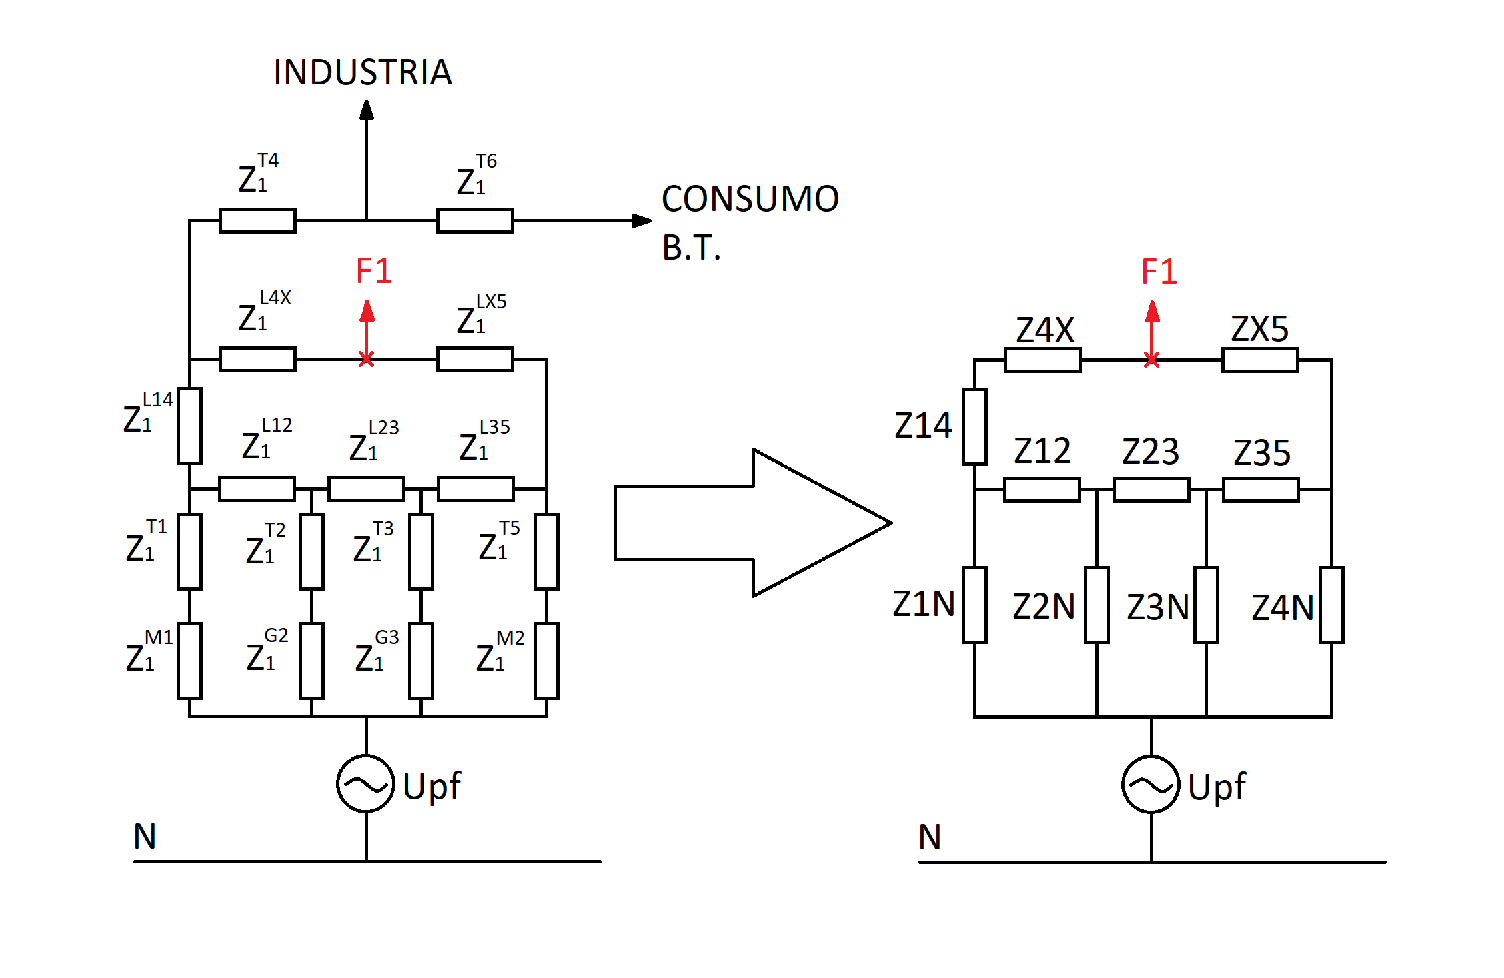

% Dibujo Circuito equivalente
imshow('F1_1.png');

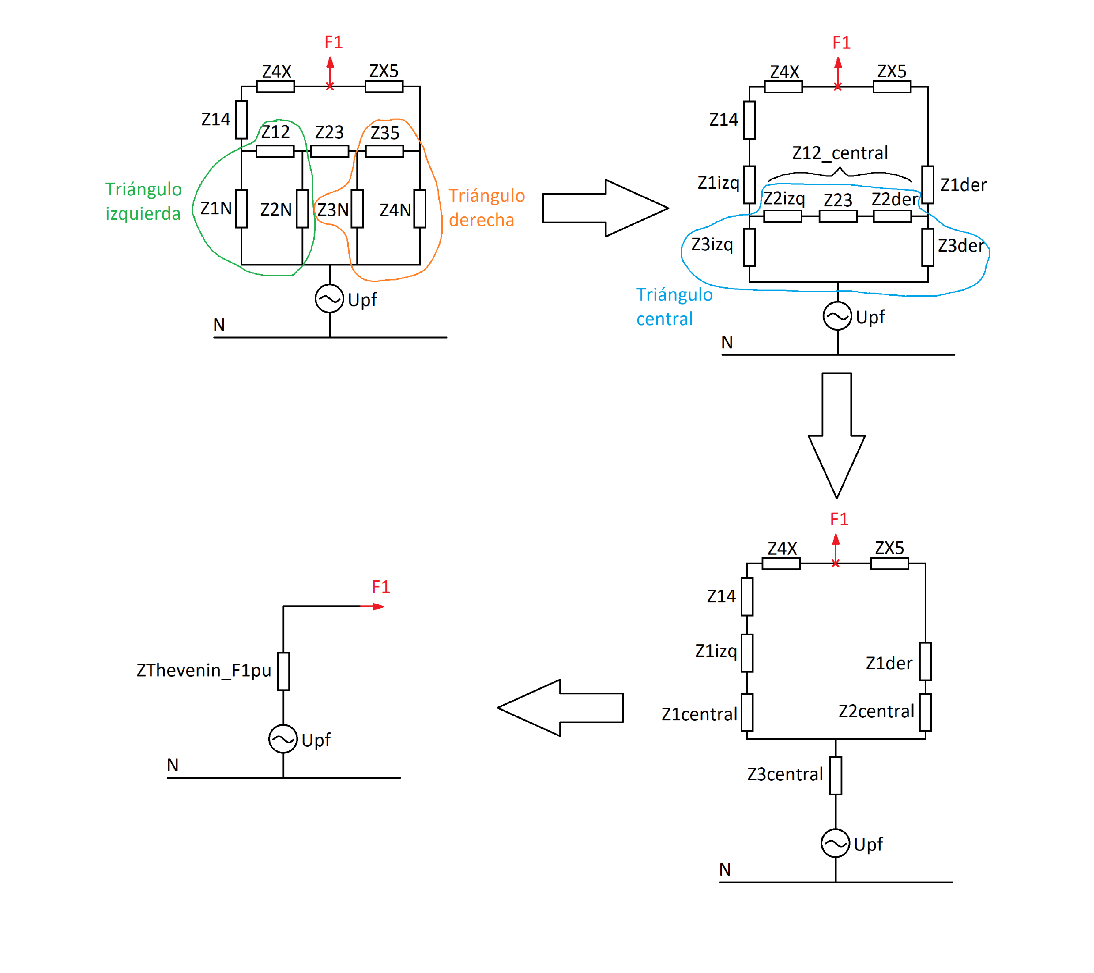


% Datos
Ubase_F1 = Ubase1;
Ibase_F1 = Sbase/(sqrt(3)*Ubase_F1);
Upf_F1 = 1.05;
% Para introducir el valor de x se debe ir al cálculo de
% impedancias en la Zona 1

% Primero calculamos el equivalente de Thèvenin del circuito
Z1N = ZT1pu(1)+ZM1pu(1);
Z2N = ZT2pu(1)+ZG2pu(1);
Z3N = ZT3pu(1)+ZG3pu(1);
Z12 = ZL12pu(1);
Z23 = ZL23pu(1);
Z35 = ZL35pu(1);
Z14 = ZL14pu(1);
Z4X = ZL4Xpu(1);
ZX5 = ZLX5pu(1);

% Dibujo procedimiento
imshow('F1_2.png');

% Triángulo de la izquierda 
[Z1izq, Z2izq, Z3izq] = Triangle2Star(Z12, Z2N, Z1N)

Z1izq =             0 +   0.033918i


Z2izq =             0 +  0.0053433i


Z3izq =             0 +     0.1984i



% Triángulo de la derecha
[Z1der, Z2der, Z3der] = Triangle2Star(Z35, Z2N, Z1N)

Z1der =             0 +    0.17505i


Z2der =             0 +   0.027577i


Z3der =             0 +    0.17919i



% Triángulo central
Z12_central = Z2izq+Z23+Z2der;
Z31_central = Z3izq;
Z23_central = Z3der;
[Z1central, Z2central, Z3central] = Triangle2Star(Z12_central, Z23_central, Z31_central)

Z1central =             0 +   0.045782i


Z2central =             0 +    0.04135i


Z3central =             0 +   0.072427i



% Calculamos la impedancia equivalente del paralelo
Zpar_izq = Z4X+Z14+Z1izq+Z1central;
Zpar_der = ZX5+Z1der+Z2central;
Zpar = Parallel(Zpar_izq, Zpar_der);

% Posteriormente, se calcula la impedancia de Thèvenin en F1
ZThevenin_F1pu = Zpar + Z3central

$$ZThevenin\_F1pu = \frac{156941439814607044608\,\left(\frac{250\,x\,\mathrm{i}}{1089}+\frac{18864173755228172263}{78470719907303522304}\,\mathrm{i}\right)\,\left(\frac{250\,x\,\mathrm{i}}{1089}-\frac{69991113892746719531}{156941439814607044608}\,\mathrm{i}\right)\,\mathrm{i}}{107719461403203064057}+\frac{2609463640691055}{36028797018963968}\,\mathrm{i}$$


% A partir de ella se calcula la intensidad de cortocircuito en pu
J1_F1pu = (Upf_F1/ZThevenin_F1pu)

$$J1\_F1pu = \frac{21}{20\,\left(\frac{156941439814607044608\,\left(\frac{250\,x\,\mathrm{i}}{1089}+\frac{18864173755228172263}{78470719907303522304}\,\mathrm{i}\right)\,\left(\frac{250\,x\,\mathrm{i}}{1089}-\frac{69991113892746719531}{156941439814607044608}\,\mathrm{i}\right)\,\mathrm{i}}{107719461403203064057}+\frac{2609463640691055}{36028797018963968}\,\mathrm{i}\right)}$$


% Finalmente, la corriente en el cortocircuito F1
J1_F1 = 3*J1_F1pu*Ibase_F1

$$J1\_F1 = \frac{484758909808928811}{351843720888320\,\left(\frac{156941439814607044608\,\left(\frac{250\,x\,\mathrm{i}}{1089}+\frac{18864173755228172263}{78470719907303522304}\,\mathrm{i}\right)\,\left(\frac{250\,x\,\mathrm{i}}{1089}-\frac{69991113892746719531}{156941439814607044608}\,\mathrm{i}\right)\,\mathrm{i}}{107719461403203064057}+\frac{2609463640691055}{36028797018963968}\,\mathrm{i}\right)}$$